# GPseudoRank by example

## Example 1: Microarray data set

We apply GPseudoRank to the following data set:

Windram et al. Arabidopsis defense against botrytis cinerea: chronology and regulation deciphered by high-resolution temporal transcriptomic analysis.  *The Plant Cell*, 2012.

The following code runs 4 MCMC chains. The plots will therefore not be fully identical to those in the GPseudoRank paper, where we ran 12 chains for a more detailed and exact convergence analysis. 

The number of chains and the function we run:

clear all;
nChains          = 4;
fHandle          = @pseudoRank;

As a function input, we need to provide the name of the .csv file containing the expression data (genes along the rows, and cells along the columns). The file may contain an additional intial row and column of text. 

fileName         = 'WindramCellNames.csv';

Each of the 4 chains is assigned an identifier for post-processing.

uniqueIdentifier = 1:nChains;
nSamples         = 100000;%as in GPseudoRank paper

Standard deviation for the informative prior on the log-lenth scale.

logPriorSDLength = 0.1; %fixed recommended setting

We sample the GP parameters at every 10th iteration of the sampling of the orders:

paramSamplingFreq =10;

We do not print the output on the screen during the sampling.

verbose          = false;

We start a new chain.

initialise       = true;

We record every 10th sample.

thinningFreq     = 10;

We do not use a fixed input seed, but clock-seed the random number generator with a chain-dependent offset. 

inputSeed        = NaN;

We use a random initial order. If you want to start from a given order specified in a csv-file, set permutationFileName accordingly. 

permuteData         = true;
permutationFileName = NaN;

We assume the same capture times as in the DeLorean pseudotime paper.

J E Reid and L Wernisch._ Pseudotime estimation: deconfounding single cell time series_. 

Bioinformatics, 32(19):2973?2980, 2016.

captureTimes = [ones([1,6]),repmat(2,[1,6]),repmat(3,[1,6]),...
    repmat(4,[1,6])];

There are two options for the spacing of the pseudotimes. If you set 'regInt = true', then they are equidistant, which is computationally more efficient, but does not account for the fact that the speed of biological development changes during the course of that development. With regInt set to 'false', GPseudoRank approximates pseudotime distances like geodesic distances on a manifold as sums of local Euclidean distances. Using regular pseudotimes when this is not justified may change the shape of the posterior distribution considerably, and the sampler may also fail to capture multi-modality. 

regInt           = false; %fixed recommended setting

The proposal distribution for the Gaussian process parameters is adapted during the first iterations of the sampler, up to burnInParams. 'stepSize' is the initial step size for the proposal, which is then adapted. 

burnInParams     = 5000; %fixed recommended setting
stepSize         = [0.01,0.01]; %fixed recommended setting

## Description of the proposal moves for the orders

- **Move 1, iterated swapping of neighbouring cells:** draw the number r of swaps uniformy from 1: n0 and then draw r swap positions from 1: (T-1), where T is the number of cells. Then for j = 1: r iterate the following: swap the cell at the selected swap position with its neighbour. 

- **Move 2, swapping of cells with short L1-distances:** select two positions i and j proportional to probability $p_{ij} \propto \exp(-{d(c_i,c_j)^2}{\delta_1})$, where d refers to the L1 distances of cells $c_i$ and $c_j$ in these positions. Move $c_i$ to position j and $c_j$ to position i.

- **Move 3, reversals:** obtain two positions i and j as in move 2 (replacing  $\delta_1$ by $\delta_2$) and reverse the ordering of all cells in between, including cells at i and j. 

- *Move 4, short random permutations: *draw a number r_2 of short permutations uniformly from 1, ... n3. For each j = 1, ... , r_2, draw a number r_3j uniformly from 3, ... ,max(n3a,3)) and a cell position k_j uniformly from 1, ... ,T - r_3j. Randomly permute the cells at positions k_j, ..., k_j + r_3j.

- **Move 5, reversing the entire ordering**

The rationale for moves 2 and 3 is that two cells which are positioned apart in the ordering should only be exchanged (move 2) or the segment between them reversed (move 3) if these cells have similar expression profiles and the smoothness of the trajectory remains intact after the move. 

The distributions for choosing moves 2 and 3 may be tempered, that is taken to the power of jj and kk, respectively, to lower acceptance rates if required. 

As applying two point estimation methods for single-cell orders (SLICER and TSCAN) leads to two very different estimates for the order, we understand that the distribution has more than one mode, in which case move 3 is the best choice. Alternatively, if we do not have this additional information, we may run some of the chains using move 3, and some chains using a combination of all moves. In case of several modes, move 3 will typically perform best, but for distributions of noisy data with only one mode, a combination of all moves was shown to converge faster in our extensive simulation study. 

J D Welch, A J Hartemink, and J F Prins. SLICER: inferring branched, nonlinear cellular trajectories from single cell RNA-seq data. *Genome Biol*, 17(1):106, 2016. 

Z Ji and H Ji. TSCAN: Pseudo-time reconstruction and evaluation in single- cell RNA-seq analysis. *Nucleic Acids Res*, 44(13):e117?e117, 2016. 

pp               = [0 0 1 0 0]; %only move 3, fixed recommended setting
delta            = [NaN,1/1000]; % delta_2 for move 3

kk = 0.1;% tempering the distribution for proposal move 3

n0 = NaN;%random value, we do not use this move
n3 = NaN;%random value, we do not use this move
n3a = NaN;%random value, we do not use this move
jj = NaN;%random value, we do not use this move

tic
parfor j=1:nChains
tic
feval(fHandle, fileName, j, nSamples, logPriorSDLength,verbose, ...
    initialise, thinningFreq,paramSamplingFreq,stepSize,inputSeed,...
    delta, pp,permuteData,captureTimes,regInt,...
permutationFileName,burnInParams,n0,n3,n3a,jj,kk);
toc
end

Starting parallel pool (parpool) using the 'local' profile ...
connected to 4 workers.
Elapsed time is 148.535583 seconds.
Elapsed time is 148.832167 seconds.
Elapsed time is 149.912287 seconds.
Elapsed time is 151.337622 seconds.


toc

Elapsed time is 181.891438 seconds.


poolobj = gcp('nocreate');
delete(poolobj);

## Postprocessing:

We plot the posterior distribution of the cell positions, using the first chain.

This first requires computing the posterior distribution of the cell positions:

computePositionsPseudoRank('WindramCellNames.csv',1,1,1800,...
[repmat(1,[1,6]),repmat(2,[1,6]),repmat(3,[1,6]),repmat(4,[1,6])],...
'WindramUncert.mat');%1 is the identifier of the chain, we discard the first
%1800 thinned samples as burn-in

Plotting the marginal posterior distributions of the cell positions:

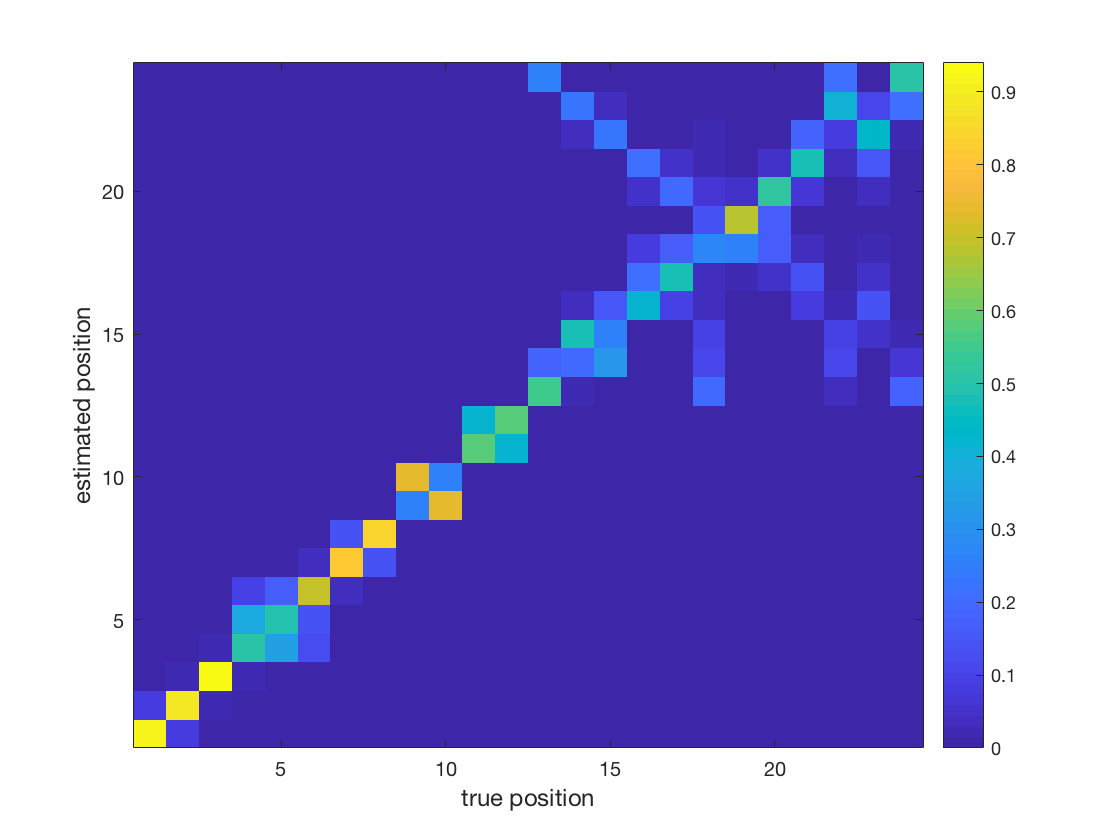

load('WindramUncert.mat');
figure()
imagesc(posFreq');
xlabel('true position','FontSize',12);
ylabel('estimated position','FontSize',12);
set(gca,'YDir','normal')
colorbar;

Computing and plotting the distribution of the distances of the orders from the true order, illustrating the bimodality of the distribution.

Computation:

nSamplesThinned = floor(nSamples/thinningFreq);
distsL1a = zeros(nChains,nSamplesThinned);
permuts1 = zeros(nSamplesThinned,24);%24 is the total number of time points

for j = 1:nChains
    orders1 = ...
        csvread(sprintf('WindramCellNames_Results_Orders_Chain%d.csv',j));
    permStart1 = csvread(sprintf('WindramCellNames_Permutation%d.csv',j));
   for k = 1:nSamplesThinned
        permuts1(k,:)  = permStart1(orders1(k,:));
    end
  
    corrCap1 = corr(permuts1',captureTimes');
    permuts1(corrCap1<0,:) = permuts1(corrCap1<0,end:-1:1);
    distsL1a(j,:) = distFromRefOrder(permuts1,1:24);
end
csvwrite('WindramDists.csv',distsL1a);

Plotting the histogram:

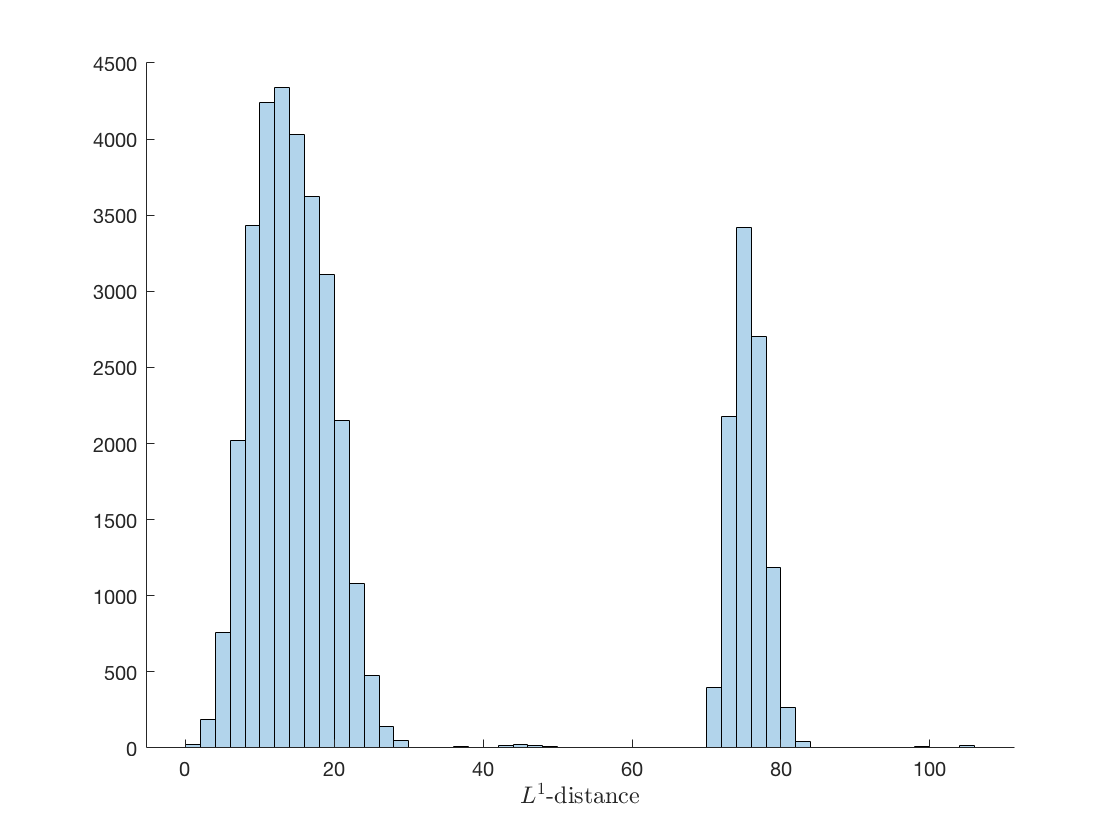

figure();
histogram(distsL1a,'FaceAlpha',0.3,'BinWidth',2);
set(gca,'box','off');
ax=gca;
ax.FontSize = 10;
xlabel('$L^1$-distance','FontSize',12,'Interpreter','Latex');

## Convergence analysis

We compute the Gelman-Rubin statistic for the log-likelihoods rather than the L1-distances, because of the bimodality of the L1-distances.

First combine the log-likelihoods of the individual chains in a single file:

nThinnedSamples = floor(nSamples/thinningFreq)

nThinnedSamples = 10000

LksWindram = [];
for j = 1:nChains
File = sprintf('WindramCellNames_Results_Chain%d.csv',j);  
 xx = dlmread(File,',',[0 0 nThinnedSamples-1 0]);
 LksWindram = [LksWindram xx];
end
csvwrite('LksWindram.csv',LksWindram);

Run the following code in R to compute the Gelman-Rubin statistic, using the coda package:

`library(coda) `

x1 = read.csv("LksWindram.csv",header = F) 

x1MC = as.mcmc.list(lapply(as.data.frame((x1)), mcmc)) 

XX1 = gelman.plot(x1MC,transform = F,autoburnin = T,bin.width = 20,max.bins=497) 

write.csv(XX1$shrink[,,1],"GRWindram_Lks.csv")

Now we can plot the Gelman-Rubin statistics:

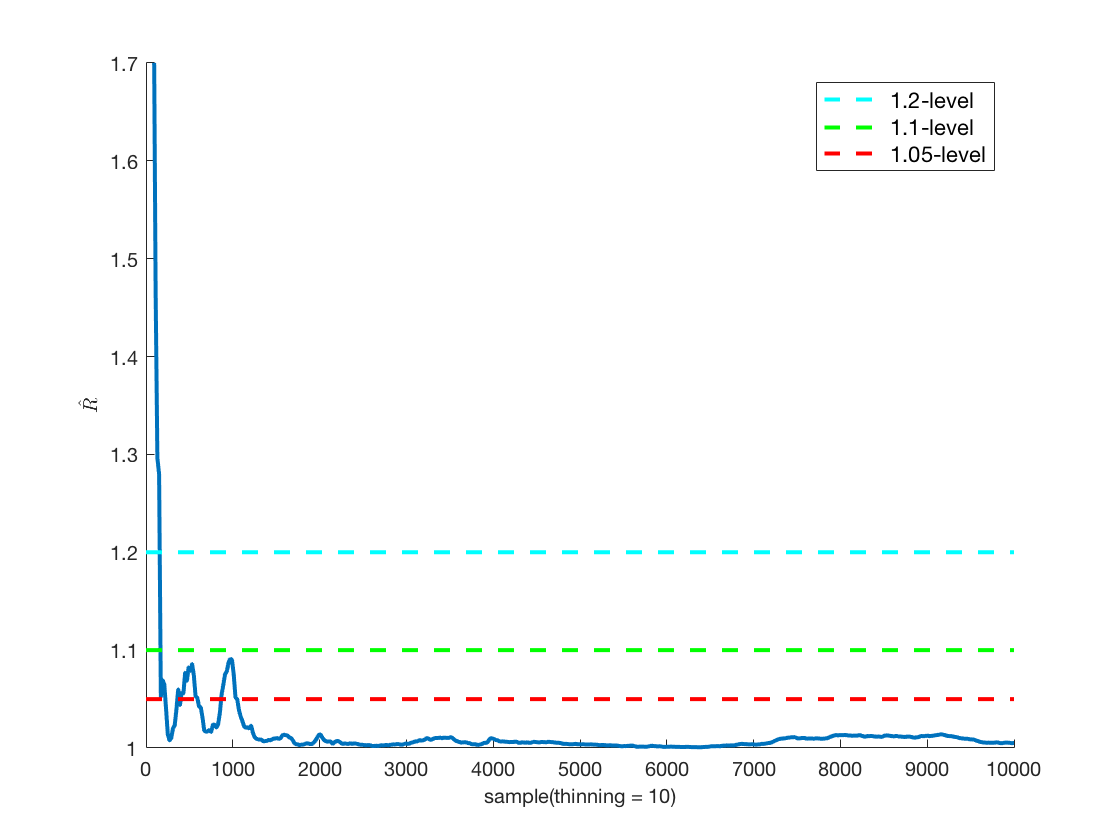

A = importdata('GRWindram_Lks.csv');
GRLk = A.data;
stepSize =  cellfun(@str2num,A.textdata(2:end,1));
figure();
plot(stepSize,GRLk,'LineWidth',2);
hold on;
h0 = refline([0,1.2]);
h0.LineWidth = 2;
h0.Color = 'c';
h0.LineStyle = '--';
h1 = refline([0,1.1]);
h1.LineWidth = 2;
h1.Color = 'g';
h1.LineStyle = '--';
h2 = refline([0,1.05]);
h2.LineWidth = 2;
h2.Color = 'r';
h2.LineStyle = '--';
ylim([1,1.7]);
xlabel('sample(thinning = 10)','FontSize',10);
ylabel('$\hat{R}$','Interpreter','Latex','FontSize',10);
set(gca,'box','off');
ax=gca;
leg = legend([h0,h1,h2],'1.2-level','1.1-level','1.05-level');
leg.FontSize = 11;

## Example 2: scRNA-seq data set

We apply GPseudoRank to an scRNA-seq data set from 

Shalek et al. Single-cell RNA-seq reveals dynamic paracrine control of cellular variation Nature, 2104. 

Logarithms of expression levels were adjusted for cell size using the method introduced by 

S Anders and W Huber. Differential expression analysis for sequence count data. *Genome Biol*, 11(10):R106?R106, 2010. 

Exact replication of the study conducted in the paper requires 12 parallel chains. The larger number of parallel chains allows more exact convergence analysis, but for general use 1 chain is sufficient. To allow any assessment of convergence using the Gelman-Rubin statistic, at least 3-4 chains are required. We use fewer iterations than in the full analysis in the GPseudoRank paper, but a sufficient number to ensure convergence according to the Gelman-Rubin statistic (see also the convergence analysis at the end of this demonstration). 

clear all;
nChains = 4;% 12 for detailed convergence analysis; 1 sufficient for general 
% use

fHandle          = @pseudoRank; 
fileName         = 'Shalek.csv';

nSamples         = 100000;

Informative priors of the model are necessary to ensure it concentrates probability mass around the correct order and to avoid that a sampling or estimation algorithm gets trapped in local modes.

priorLogSDLength = 0.01;%standard deviation of prior of log-length scale, 
% recommended value
paramSamplingFreq =10; %sampling parameters for every kth order
verbose          = false; % Whether or not to print output to screen
initialise       = true;  % If you have to stop the sampler, and then 
% %wish to rerun at a later date, set this to false 
thinningFreq     = 10;     % If set to X, records every X-th sample
inputSeed        = NaN;  %use clock seed with chain-dependent offset

delta is a concentration parameter for the distribution to choose pairs of cells for moves 2 (swaps of cells close in terms of L1-distance) and move 3 (reversal of the path between such two cells); the lower delta, the less the concentration. Decrease delta in case of very high acceptance rates.

delta            = [1/4000,1/4000];

We apply each move of the proposal distribution with the same probability, except the reversal of the entire path, which is applied with a probability of 0.002.

pp               = [0.2495 0.2495 0.2495 0.2495 0.002];

Start with a random permutation:

permuteData      = true;

The times at which the cells were captured:

captureTimes = [repmat(0,[1,49]),repmat(1,[1,75]),repmat(2,[1,65]),...
    repmat(4,[1 60]),repmat(6,[1 58])];

With regInt = false, the pseudotime distances between cells are adapted to different speeds of biological development over the course of the reaction.

regInt           = false;%fixed recommended setting

permutationFileName = NaN: uses a random permutation, if the name of a .csv file was specified here, than the permutation specified in that file would be used.

permutationFileName = NaN;

The intial step size for the GP parameters, adapted during the first 5000 iterations. 

stepSize = [0.1,0.1];%fixed recommended setting

We use the default settings for the proposal distribution of the moves, as described in the GPseudoRank paper. 

%default
n0 = max(floor(307/4),1);
        n3 = max(1,floor(307/20));
        n3a = max(3,floor(307/12));
        kk = 1;
        jj = 1;

Running nChains MCMC chains in parallel with different random starting paths. This takes a bit of time (~25 minutes on the laptop on which it was tested, see 'elapsed time' below), but you may skip this and proceed to the post-processing using the output files provided. 

tic
parfor j = 1:nChains
feval(fHandle, 'Shalek.csv', j, nSamples, priorLogSDLength, verbose,...
    initialise,thinningFreq, paramSamplingFreq,stepSize,inputSeed, ...
    delta, pp,permuteData,captureTimes,regInt,permutationFileName,...
    5000,n0,n3,n3a,jj,kk);
end

Starting parallel pool (parpool) using the 'local' profile ...
connected to 4 workers.


toc

Elapsed time is 1619.934508 seconds.


delete(gcp('nocreate'));

## Uncertainty of cell positions

The uncertainty of the cell positions changes over the course of the response to the infection.

First we compute the distribution of the posterior cell positions from the

output files of the GPseudoRank algorithm.

burnIn = 5000;%number of thinned samples to be discarded as burn-in
% 1:nChains refers to the identifieres of the MCMC chains and the initial
% permutations, the output is saved in the file 'ShalekUncertA.mat'
computePositionsPseudoRank('Shalek.csv',1:nChains,1:nChains,burnIn,...
    captureTimes,'ShalekUncertA.mat');

Plotting the posterior distributions of the cell positions: we see that the uncertainty decreases, once the reaction of the cells to the stimulant has set in, and becomes much larger again towards the end of the observed pseudotime range. This is relevant for downstream analyes such as the subsequent application of clustering or network methods for time series data, whose accuracy may benefit from focusing on the less uncertain part of the pseudotime series. 

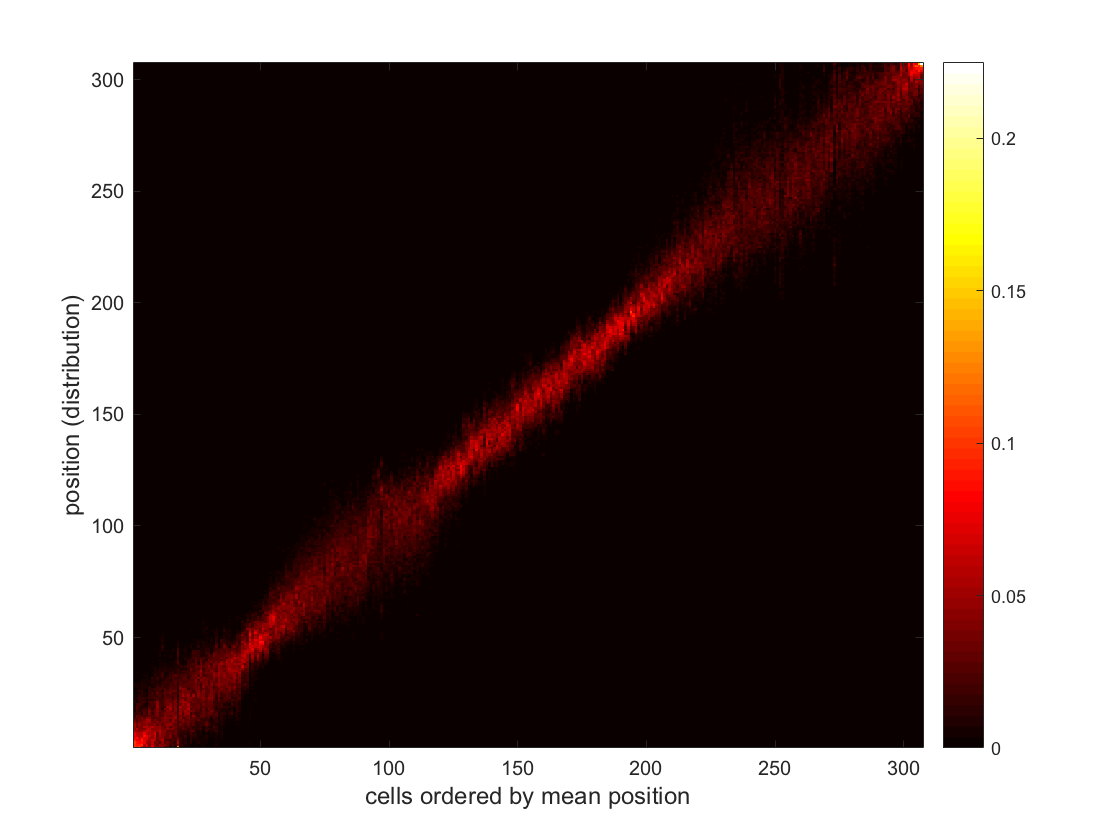

set(0,'DefaultAxesFontName', 'Arial')
set(0,'DefaultAxesFontSize', 10)
set(0,'defaultfigurecolor',[1 1 1]);
load('ShalekUncertA.mat')
A = mean(posFreq,3);
% computing the average mean position
xx = mean(xx,2);
[sorted_xx xxI] = sort(xx);
figure()
colormap(hot);
imagesc(A(xxI,:)');
xlabel('cells ordered by mean position','FontSize',12);
ylabel('position (distribution)','FontSize',12);
set(gca,'YDir','normal')
ax= gca;
c=colorbar;

## Uncertainty of the distributions of the orders

The first step is to compute the L1-distances of each posterior sample of cell positions from a reference order (1:307). The reference order may be any arbitray order. The plot illustrates the uncertainty of the order of the cells.

nSamplesThinned = floor(nSamples/thinningFreq);
distsL1a = zeros(nChains,nSamplesThinned);
permuts1 = zeros(nSamplesThinned,307);%307 is the total number of cells

for j = 1:nChains
    orders1 = csvread(sprintf('Shalek_Results_Orders_Chain%d.csv',j));
    permStart1 = csvread(sprintf('Shalek_Permutation%d.csv',j));
   for k = 1:nSamplesThinned
        permuts1(k,:)  = permStart1(orders1(k,:));
    end
  
    corrCap1 = corr(permuts1',captureTimes');
    permuts1(corrCap1<0,:) = permuts1(corrCap1<0,end:-1:1);
    distsL1a(j,:) = distFromRefOrder(permuts1,1:307);
end
csvwrite('ShalekDistFromRefL1Irreg.csv',distsL1a);

Now we illustrate the densities of the L1-distances using a histogram:

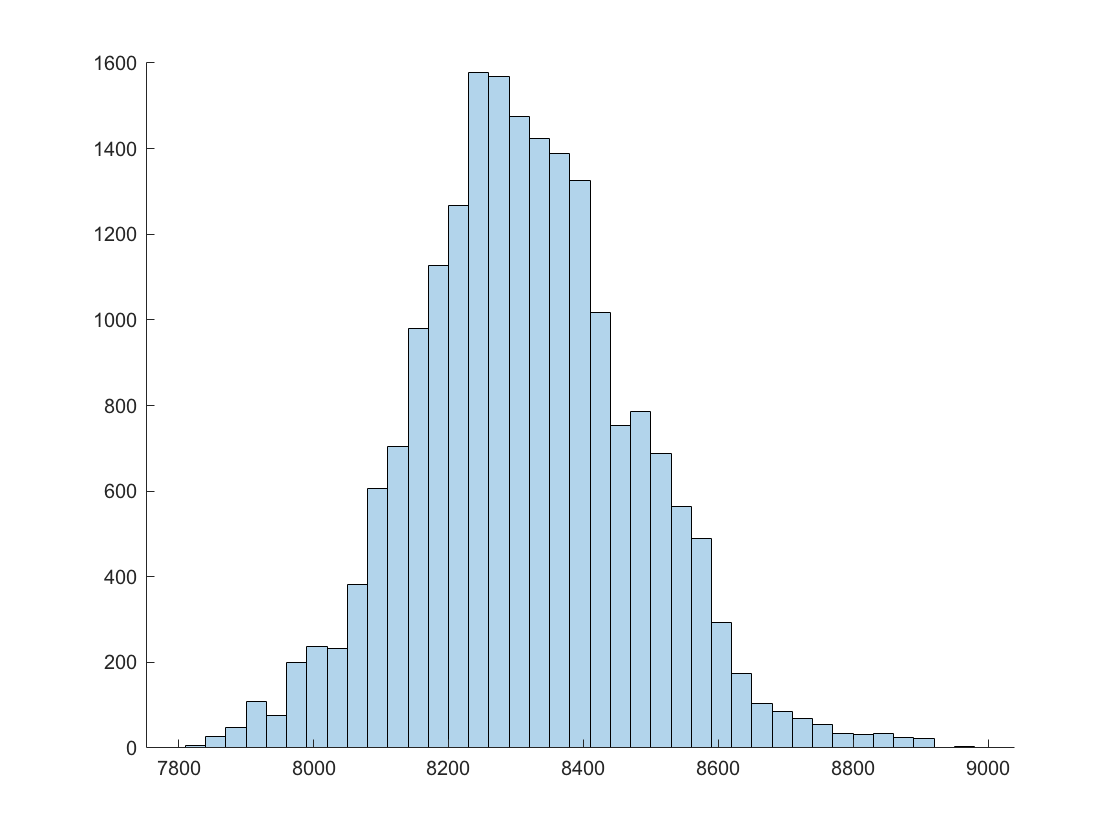

figure();
A = dlmread('ShalekDistFromRefL1Irreg.csv',',',...
    [0 burnIn nChains-1 nSamplesThinned-1]);
a = min([min(A)]);
b = max([max(A)]);
xlabel('$L^1$-distance','FontSize',10,'Interpreter','Latex');
set(gcf, 'PaperUnits', 'centimeters');
histogram(A(:),'BinEdges', a:30:b,'FaceAlpha',0.3);
set(gca,'box','off');

## Convergence analysis

First we compute the Gelman-Rubin Rhat statistic for the L1-distances of the sampled cell positions from the reference permutation 1:307.

Run the following code in R to compute the Gelman-Rubin statistic, using the coda package:

`library(coda)`

x1 = read.csv("ShalekDistFromRefL1Irreg.csv",header = F) 

x1MC = as.mcmc.list(lapply(as.data.frame(t(x1)), mcmc)) 

X1 = gelman.plot(x1MC,transform = F,autoburnin = T,bin.width = 20,max.bins=497) 

write.csv(X1$shrink[,,1],"GRShalek.csv")

We also compute the Gelman-Rubin statistic for the log-likelihoods.

First combine the log-likelihoods of the individual chains in a single file:

LksShalek = [];
for j = 1:nChains
File = sprintf('Shalek_Results_Chain%d.csv',j);  
 xx = dlmread(File,',',[0 0 nSamplesThinned-1 0]);
 LksShalek = [LksShalek xx];
end
csvwrite('LksShalek.csv',LksShalek);

Run the following code in R to compute the Gelman-Rubin statistic, using the coda package:

`library(coda) `

x1 = read.csv("LksShalek.csv",header = F) 

x1MC = as.mcmc.list(lapply(as.data.frame((x1)), mcmc)) 

XX1 = gelman.plot(x1MC,transform = F,autoburnin = T,bin.width = 20,max.bins=497) 

write.csv(XX1$shrink[,,1],"GRShalek_Lks.csv")

Now we can plot the Gelman-Rubin statistics. For convergence, a value for the statistic below 1.1 is preferable, though 1.2 is considered sufficient in

SP Brooks and A Gelman. General methods for monitoring convergence of iterative simulations. 

*J Comput Graph Stat*, 7(4): 434:455, 1998. 

1.1 is recommended in 

A Gelman and K Shirley. Inference from simulations and monitoring convergence. In S Brooks, A Gelman, G Jones, and X-L Meng, editors, *Handbook of Markov Chain Monte Carlo*, volume 6, pages 163:174. CRC, Boca Raton, 2011. 

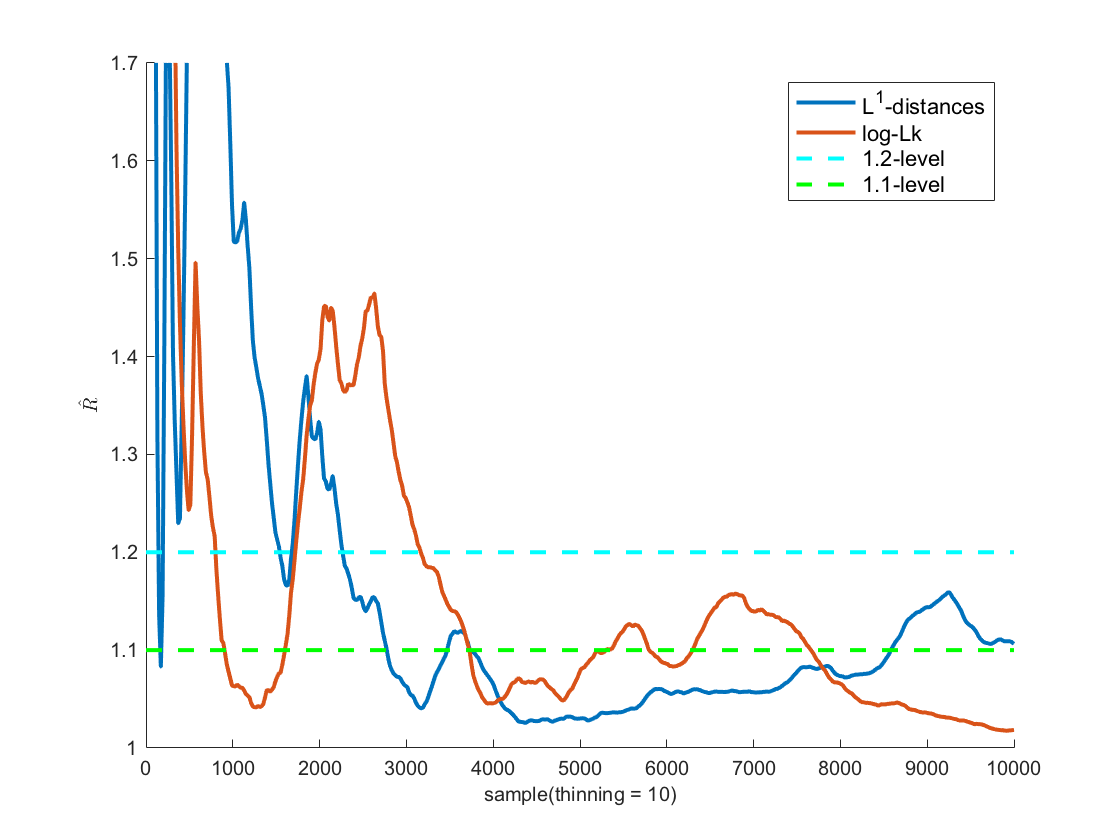

A = importdata('GRShalek.csv');
GRL1 = A.data;
GRLk = csvread('GRShalek_Lks.csv',1,1);
stepSize =  cellfun(@str2num,A.textdata(2:end,1));
figure();
plot(stepSize,GRL1,'LineWidth',2);
hold on;
plot(stepSize,GRLk,'LineWidth',2);
hold on;
h0 = refline([0,1.2]);
h0.LineWidth = 2;
h0.Color = 'c';
h0.LineStyle = '--';
h1 = refline([0,1.1]);
h1.LineWidth = 2;
h1.Color = 'g';
h1.LineStyle = '--';
ylim([1,1.7]);
xlabel('sample(thinning = 10)','FontSize',10);
ylabel('$\hat{R}$','Interpreter','Latex','FontSize',10);
set(gca,'box','off');
ax=gca;
leg = legend('L^1-distances','log-Lk','1.2-level','1.1-level');
leg.FontSize = 11;